# **ELEC-H-313 : Instrumentation**

# *Laboratoire 4: Filtres analogiques*

## Information préliminaire

Le laboratoire se déroule au sein d'un "LiveScript" MATLAB. Ce dernier contient du code qu'il faut compléter afin de répondre aux différents exercices.

Si vous n'êtes pas familier avec l'éditeur MATLAB et les commandes usuelles, il est conseillé de réaliser le tutoriel [MATLAB Onramp](https://fr.mathworks.com/learn/tutorials/matlab-onramp.html) avant le laboratoire.

## Toolboxes requises

Cette séance nécessite les toolboxes suivantes:

- [Signal Processing Toolbox](https://nl.mathworks.com/products/signal.html)

- [Control System Toolbox](https://nl.mathworks.com/products/control.html)

## Objectifs du laboratoire

- Observer l’allure des différents types de filtres

- Comprendre la méthodologie de dimensionnement d’un filtre passe-bas de type Butterworth

- Utiliser des outils de dimensionnement de filtres

- Comprendre la transformation de filtres passe-bas normalisés vers les autres types de filtres

## Rappels

Un filtre est caractérisé par une fonction de transfert:


$$H{\left(jw\right)}=\frac{V_{out} \left(\textrm{jw}\right)}{V_{in} \left(jw\right)}={\left∣H{\left(jw\right)}\right∣}e^{j\ \mathrm{a}\mathrm{r}\mathrm{g}\left(H{\left(jw\right)}\right)}$$


Selon la partie du spectre atténué, le filtre porte le nom de:

- Passe-haut (suppression des basses fréquences)

- Passe-bas (suppression des hautes fréquences)

- Coupe-bande (suppression d’une bande de fréquence)

- Passe-bande (suppression de tout le spectre à l’exception d’une bande de fréquence)

Un filtre est toujours caractérisé par deux paramètres: sa fréquence de coupure $f_{c\;}$ ( fréquence où l'atténuation vaut -3dB) et son ordre $n$. Dans le cas des filtres passe-bande et coupe-bande, le facteur de qualité $q=\frac{\textrm{fréquence}\;\textrm{centrale}}{\;\textrm{largeur}\;\textrm{de}\;\textrm{bande}}$ reflète la sélectivité de la bande-passante ou de la bande d'arrêt. Pour un filtre PB ou PH, le facteur de qualité représente l'amplitude de la fréquence de résonance.

La fonction de transfert d'un filtre peut être optimisée afin de privilégier un gain constant dans la bande-passante, la sélectivité ou encore la linéarité de la réponse en phase. C'est ce qu'on appelle le choix de l'approximation. Puisque ce choix affecte la fonction de transfert, il détermine également la facteur de qualité. Symétriquement, si l'on modifie q, on change alors légèrement la fonction de transfert et donc l'approximation utilisée. Une approximation de type Butterworth par exemple, permet de minimiser la résonance et donc d'assurer que le gain dans la bande-passante reste constant (Q = 0.707).

Les filtres analogiques sont réalisés en pratique avec des composants analogiques. Il existe plusieurs topologies disponibles selon l'ordre du filtre (filtre RC, Sallen-Key, Multiple Feedback, ...) qui ont des caractéristiques réelles variées (une sensibilité plus ou moins grande à la tolérance des composants, le bruit généré, ...) selon les conditions d'utilisation.

clearvars %clear the workspace
clc
cd(fileparts(matlab.desktop.editor.getActiveFilename)); %Changes location to script directory

# Exercice 1: Analyse des différentes approximations

Observez l'impact du choix de la fréquence de coupure, de la bande- passante et de l'ordre sur la courbe de Bode pour chaque type de filtre filtre et pour chaque approximation. Déterminez-en les avantages et inconvénients de chaque approximation.

f = logspace(0,3.6,500); %plot bandwidth (1Hz-3.5kHz)
w = 2*pi*f;
fc =1500; %cut-off frequency parameter
BW = 1010; %Bandwidth of bandpass and bandstop filter
wc = 2*pi*fc;
n =1; %filter order
filterType = "low"; %type of filter
if filterType == "bandpass" || filterType == "stop"
    wc = [max(1,wc-BW) wc+BW];
end 

%Ideal brick wall low pass filter
brickMag = zeros(1,500);
brickPhase = zeros(1,500);
if filterType == "low"
    [ ~, idx ] = min( abs( f-fc ) );
    brickMag(idx:end) = -59;
    brickPhase(idx:end) = -n*pi/2;
end

%Butter filter
[bb,ab] = butter(n,wc,filterType, 's'); %returns the transfer functionr
[hb,wb] = freqs(bb,ab,w); %computes the magnitude and phase of the filter

%Chebischev filter
[bch,ach] = cheby1(n,3,wc,filterType, 's'); %returns the transfer function
[hch,wch] = freqs(bch,ach,w); %computes the magnitude and phase of the filter

%Bessel filter
[bbess,abess] = besself(n,wc,filterType); %returns the transfer function
[hbess,wbess] = freqs(bbess,abess,w); %computes the magnitude and phase of the filter

%Elliptic filter
[be,ae] = ellip(n,3, 30,wc,filterType, 's'); %returns the transfer function
[he,we] = freqs(be,ae,w); %computes the magnitude and phase of the filter

%% Bode plots
figure
subplot(2,1,1)
hold on
if filterType == "low"
    plot(f, brickMag)
end
plot(wb/(2*pi),mag2db(abs(hb)))
plot(wch/(2*pi),mag2db(abs(hch)))
plot(wch/(2*pi),mag2db(abs(he)))
plot(wch/(2*pi),mag2db(abs(hbess)))
axis([0 3500 -60 5])
grid on
xlabel('Frequency (Hz)')
ylabel('Attenuation (dB)')
if filterType == "low"
    legend('ideal', 'butter','chebi', 'ellip', 'bessel')
else
    legend('butter','chebi', 'ellip', 'bessel')
end
 
subplot(2,1,2)
hold on
if filterType == "low"
    plot(f, brickPhase)
end
plot(wb/(2*pi),unwrap(angle(hb)));
plot(wch/(2*pi),unwrap(angle(hch)));
plot(we/(2*pi),unwrap(angle(he)));
plot(wbess/(2*pi),unwrap(angle(hbess)));
axis([0 3500 -n*pi/2 n*pi/2])
grid on
xlabel('Frequency (Hz)')
ylabel('Phase (degrees)')

# Exercice 2: Approximation de Butterworth

Un système linéaire, étant caractérisé par une fonction de transfert rationnelle en p, ne permettra jamais de réaliser la caractéristique idéale de filtrage (mur de brique), mais seulement de s’en approcher.

Pour un filtre passe-bas, la fonction de transfert rationnelle en p est de type :

            
$$H{\left(p\right)}=\frac{G}{\sum_{m=0}^n a_m p^m }$$
  

où G= gain (usuellement =1), n = ordre du filtre et les coefficients $a_{m\;}$dépendent de l'approximation choisie. Le polynôme au dénominateur est appelé **polynôme de (nom de *****l'approximation*****). **On peut également exprimer la fonction de transfert en fonction des ses pôles:


$$H\left(p\right)=\frac{G}{\left(p-p_1 \right)\left(p-p_2 \right)\left(p-p_3 \right)\ldotp \ldotp \ldotp \left(p-p_n \right)}=\frac{G}{\;\prod_{k=1}^n \left(p-p_{k\;} \right)}$$


Pour une approximation de Butterworth, le module de la fonction de transfert d'un filtre est donné par:


$${\left∣H{\left(jw\right)}\right∣}=\frac{1}{\sqrt{1+{\left(\frac{\omega }{w_{c\;} }\right)}^{2n} }}\$$


ce qui donne pour une filtre normalisé $\left(f_c =1\frac{\textrm{rad}}{s}\right)$:


$${\left∣H{\left(jw\right)}\right∣}=\frac{1}{\sqrt{1+\omega^{2n} }}\$$


**On vous demande de dimensionner un filtre Butterworth qui respecte le gabarit** (régions de tolérance pour la bande passante et la bande d'arrêt à respecter) donné ci-dessous. L'annexe "*Dimensionnement d'un filtre analogique de type Butterworth*" vous renseigne sur la méthode de l'approximation de Butterworth à utiliser et qui se base sur le module d'un filtre Butterworth. Des méthodes similaires existent pour les autres approximations.

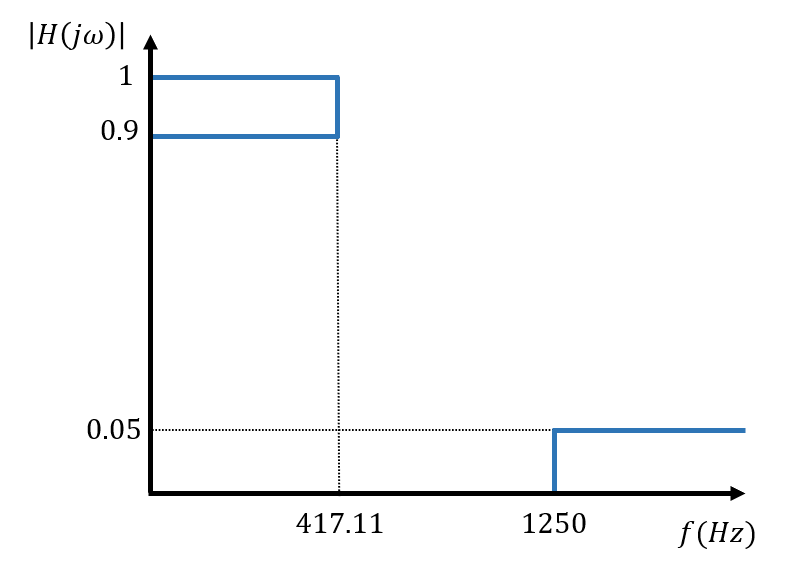

On se concentrera ici sur la création d'un prototype de filtre passe-bas, puisque les autres types de filtres peuvent être facilement obtenus avec une simple transformation.

1. Sur papier, déterminez l'ordre n minimum du filtre.

2. Sur papier, déterminez la fréquence de coupure **pour réaliser la bande passante exactement**.

3. Déterminez les pôles de la fonction de transfert **normalisée** et déduisez-en son expression H(p).

clearvars;
pNormalized = zeros(1,8);
% numberofPoles =   ;%number of poles
for k = 1:numberofPoles
%     pNormalized(k) =  ;
end
disp('poles FT normalisée:')
disp(pNormalized)
filterNormalized = tf(1,[1 0.765 1]) * tf(1, [1 1.848 1]) %FT normalisée

4. Le code ci-dessous permet de déterminer les pôles de la fonction de transfert **non normalisée. Expliquez.**

p500 = zeros(1,8);
for k = 1:8
    p500(k) = 1j*exp(1j*pi/8*(2*k-1))*2*pi*500;
end
disp('poles @500Hz:')
disp(p500)
filter500Hz = tf(9.74e13,[1 2404.5 9.8e6])*tf(1,[1 5804.9 9.87e6]) %FT @fc = 500Hz

5. Vérifiez l'allure (fréquence de coupure, atténuation, ...) du filtre Butterworth que vous avez déterminé.

figure('Name', 'Bode plot filter')
bode(filter500Hz)
grid on

# Exercice 3: Transformation des prototypes passe-bas

En pratique, les polynômes au dénominateur des fonctions de transfert normalisées sont tabulés pour toutes les approximations couramment utilisées et il n'est donc pas nécessaire de les calculer. Par exemple, pour une approximation Butterworth:

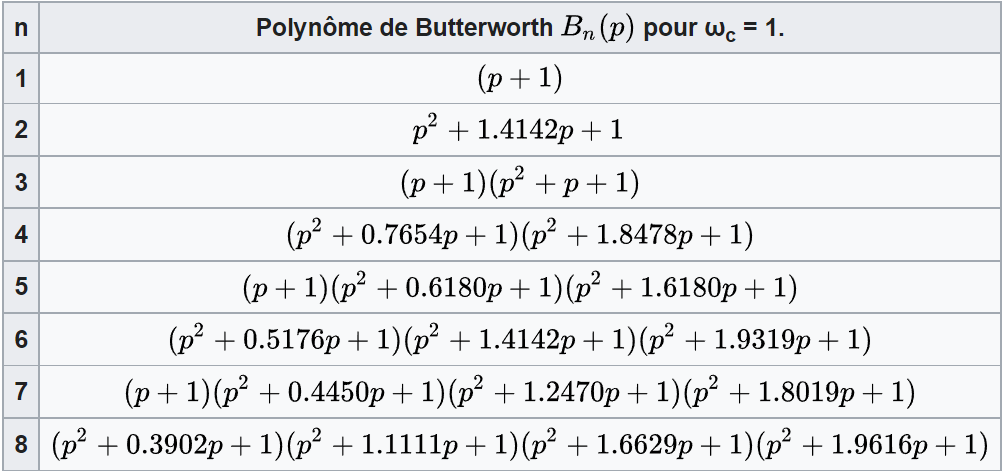

Et il est trivial d'obtenir la fonction de transfert non normalisée, pour une pulsation $w_c$, avec un simple changement de variable tel que $H\left(p\right)=\overset{~}{H} \left(\frac{p}{\omega_c }\right)\;$.

1.  Appliquez cette méthode afin d'obtenir la fonction de transfert d'un filtre Butterworth d'ordre 1 avec une fréquence de coupure de 500Hz et vérifier graphiquement son allure. Utilisez la fonction [tf](https://fr.mathworks.com/help/control/ref/tf.html) pour calculer la fonction de transfert.

clearvars;
wc = 2*pi*500;
% PB500Hz =   %FT @fc = 500Hz
figure('Name', 'Bode plot LP filter')
bode(PB500Hz)
grid on

2. Matlab fournit également des fonctions qui permettent de faire la transformation directement. Utilisez la fonction [lp2lp](https://nl.mathworks.com/help/signal/ref/lp2lp.html) (low-pass to low-pass) pour obtenir un filtre passe-bas d'ordre 2 avec $f_c =500\textrm{Hz}$ à partir de la fonction de transfert normalisée (à déterminer avec la fonction [tf](https://fr.mathworks.com/help/control/ref/tf.html)).

wc = 500*2*pi;
% Normalized =  %normalized TF
b = Normalized.num{1}; %stores tf's numerator in "b"
a = Normalized.den{1}; %stores tf's denominator in "a"

% [numPB500,denPB500] =  ;%use lp2lp to compute new num and den of the TF
PB500 = tf(numPB500,denPB500);
hold on
bode (PB500)
legend('n = 1', 'lp2lp n=2')
grid on

## Passage vers un filtre passe-haut non normalisé

Matlab fournit également la fonction [buttap](https://nl.mathworks.com/help/signal/ref/buttap.html) qui permettent d'obtenir les zéros, les poles et le gain d'un prototype de filtre Butterworth d'un ordre donné sans avoir recours à un tableau. Il suffit alors de transformer cette notation "zéro,pôles,gain (zpk)" en une notation "numérateur,dénominateur" d'une fonction de transfert puis d'utiliser la fonction [lp2hp](https://nl.mathworks.com/help/signal/ref/lp2hp.html) pour obtenir le filtre passe-haut équivalent. Utilisez cette méthode pour obtenir un filtre passe-haut d'ordre 4 avec $f_c =1k\textrm{Hz}$.

**Notez que la transformation à réaliser en pratique est:**


$$H\left(p\right)=\overset{~}{H} \left(\frac{\omega_c }{p}\right)$$


clearvars;
% wc =  ;
% [z,p,k] =  ; %computes prototype butter filter
[num,den] = zp2tf(z,p,k); %get num and den from zero, pole and gain
% [numPH,denPH] =  ; %use lp2hp
newPH500 = tf(numPH,denPH);
figure('Name', 'Bode plot HP filter')
bode(newPH500,{1e2,1e5}) %limit axis from 100->100 000Hz
grid on

## Passage vers un filtre passe-bande non normalisé

La même méthode peut être appliquée pour obtenir un filtre passe-bande avec la fonction [lp2bp](https://nl.mathworks.com/help/signal/ref/lp2bp.html). Utilisez cette méthode pour obtenir un filtre passe-bande d'ordre 4 avec $f_0 =1k\textrm{Hz}$ et une largeur de bande de 100Hz.

**Notez que la transformation à réaliser en pratique est:**


$$H\left(p\right)=\overset{~}{H} \left(\frac{\textrm{p²}+w_0 ²}{\textrm{Bp}}\right)$$


où $B$ et $w_0$ sont respectivement la largeur de bande (différence entre les deux fréquences où le gain a chuté de 3dB) et la fréquence centrale (moyenne géométrique des extrémités des bandes passantes, ou moyenne arithmétique sur un graphique logarithmique) du filtre:                             


$$B=\omega_{c^+ } -\omega_{c^- } \$$


 
$$\left.\ \omega_0 ={sqrt\left(\omega \right.}_{c^+ } \ldotp \omega_{c^- } \ \right)$$


% w0 =  ;
% B =  ;
% [z,p,k] =  ; %computes prototype butter filter
[num,den] = zp2tf(z,p,k); %get num and den from zero, pole and gain

% [numBP,denBP] =  ;%use lp2bp
newCBande500 = tf(numBP,denBP);
figure('Name', 'Bode plot BP filter')
bode(newCBande500)
grid on

## Passage vers un filtre coupe-bande non normalisé

La même méthode peut être appliquée pour obtenir un filtre coupe-bande avec la fonction [lp2bs](https://nl.mathworks.com/help/signal/ref/lp2bs.html). Utilisez cette méthode pour obtenir un filtre coupe-bande d'ordre 4 avec $f_0 =1k\textrm{Hz}$ et une large de bande de 500Hz.

**Notez que la transformation à réaliser en pratique est:**


$$H\left(p\right)=\overset{~}{H} \left(\frac{\textrm{Bp}}{\textrm{p²}+w_0 ²}\right)$$


% à l'aide d'une fct Matlab
% w0 =  ;
% B =  ;
% [z,p,k] =  ; %computes prototype butter filter
[num,den] = zp2tf(z,p,k); %get num and den from zero, pole and gain

% [numBP,denBP] =  ;%use lp2bs
newCBande500 = tf(numBP,denBP);
figure('Name', 'Bode plot BS filter')
bode(newCBande500)
grid on

# Exercice 4: Filtre réjecteur de fréquence

Il est possible de réaliser un filtre passif coupe-bande de premier ordre avec ce circuit:

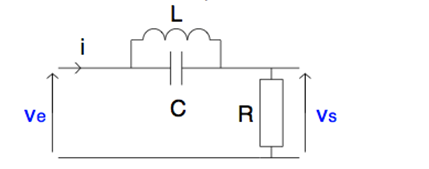

1. Sur papier, calculez la fonction de transfert H(p) de ce circuit et démontrez qu'il s'agit bien d'un filtre coupe-bande. 

2. Dimensionner les composants de façon à rejeter la fréquence 50Hz.

3. Exprimer la fonction de transfert de ce filtre coupe-bande d'ordre 1 sous sa forme canonique $H\left(p\right)=\frac{\textrm{p²}+\omega {\;}_{0\;} ²}{\;\textrm{p²}+p\frac{\omega_{0\;} }{\;q}+\omega_0 ²\;}$  et déduisez-en $\omega_0$ et $q$ en fonction de R, C et L. 

4. Sur base de la fonction de transfert canonique, vérifiez dans Matlab l’allure du filtre réalisé (fréquence de coupure, facteur de qualité, …) et observer l’effet d’une variation du facteur de qualité q.

clearvars,
q = [1 2 10]; %q variation

% w0 =  ;
CB1 = tf([1 0 w0^2],[1 w0/q(1) w0^2]);
CB2 = tf([1 0 w0^2],[1 w0/q(2) w0^2]);
CB3 = tf([1 0 w0^2],[1 w0/q(3) w0^2]);

figure('Name', 'BS RLC filter')
opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.XLim={[5e1 2e3]};
opts1.YLim={[-30 0]};
hold on
bodeplot(CB1, opts1)
bodeplot(CB2, opts1)
bodeplot(CB3, opts1)
legend('q = 1', 'q = 2', 'q = 10')
grid on

En général, on essaie d’éviter d’utiliser des inductances pour le design de filtres à largeur de bande étroite et à faible fréquence de coupure.

- Les inductances de grandes valeurs (>100mH) sont physiquement grandes et chères (>10€, plusieurs cm de côté) .

- Une inductance possède généralement une résistance parasite en série (dûe à la conductance non nulle du fil) et une capacité parasite en parallèle (capacité entre les fils de la bobine) qui impactent les performances du montage.

- Les inductances que l’on achète dans le commerce sont généralement peu précises (large tolérance de l'ordre de 20 à 50% au minimum).  

5. Vérifiez quantitativement l’impact d’une tolérance de 10% sur la valeur de l’inductance sur la fréquence centrale de réjection du filtre vu au point précédent (sur papier). Comparez ensuite les diagrammes de Bode ci-dessous.

%Realistic component values
R = 3.1e3; %3.1kOhms
L = 1; %1H
L2 = 1.1; %10percent tolerance
C = 1e-5; %10µF
q = sqrt(C)*R/sqrt(L)
f0 = (1/sqrt(L*C))/(2*pi)
q2 = sqrt(C)*R/sqrt(L2)
f02 = (1/sqrt(L2*C))/(2*pi)


figure
w = logspace(2.2,2.8, 300);
reject1 = tf([1 0 1/(L*C)],[1 1/(R*C) 1/(L*C)]);
reject2 = tf([1 0 1/(L2*C)],[1 1/(R*C) 1/(L2*C)]); %with 10percent tolerance

opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.XLim={[2e2 6e2]};
opts1.YLim={[-25 0]};
bodeplot(reject1, opts1,w)
hold on
bodeplot(reject2,opts1,w)
grid on
legend('ideal', 'with tolerance', 'Location', 'southwest');

6. Vérifiez, qualitativement en analysant le circuit et quantitativement via la fonction de transfert, l’impact d’une résistance parasite série sur la réjection du 50Hz (sur papier).

%Realistic component values
R = 3.1e3; %3.1kOhms
L = 1; %1H
L2 = 1.1; %10percent tolerance
C = 1e-5; %10µF
q = sqrt(C)*R/sqrt(L)
f0 = (1/sqrt(L*C))/(2*pi)
q2 = sqrt(C)*R/sqrt(L2)
f02 = (1/sqrt(L2*C))/(2*pi)
ESR = 20; %added ESR of 20ohms


figure
w = logspace(2.2,2.8, 300);
reject1 = tf([1 0 1/(L*C)],[1 1/(R*C) 1/(L*C)]);
reject2 = tf([1 0 1/(L2*C)],[1 1/(R*C) 1/(L2*C)]); %with 10percent tolerance
reject3 = tf([1 ESR/L 1/(L*C)],[1 (ESR/L)+(1/(R*C)) (ESR/(R*L*C))+(1/(L*C))]); %added ESR

opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.XLim={[2e2 6e2]};
opts1.YLim={[-25 0]};
bodeplot(reject1, opts1,w)
hold on
bodeplot(reject2,opts1,w)
bodeplot(reject3,opts1,w)
grid on
legend("ideal", "with tolerance", "with ESR", "Location", "Southwest")

**On préfère donc utiliser des filtres actifs (sans inductance avec des amplis opérationnels) pour réaliser ce type de filtres, car ils ne présentent pas ces inconvénients.**